# Simulate the Glucose-Insulin Response

This example shows how to simulate and analyze a model in SimBiology® using a physiologically based model of the glucose-insulin system in normal and diabetic humans.

## References

- Meal Simulation Model of the Glucose-Insulin System. C. Dalla Man, R.A. Rizza, and C. Cobelli. *IEEE Transactions on Biomedical Engineering* (2007) 54(10), 1740-1749.

- A System Model of Oral Glucose Absorption: Validation on Gold Standard Data. C. Dalla Man, M. Camilleri, and C. Cobelli. *IEEE Transactions on Biomedical Engineering* (2006) 53(12), 2472-2478.

## Aims

- Implement a SimBiology model of the glucose-insulin response.

- Simulate the glucose-insulin response to one or more meals for normal and impaired (diabetic) subjects.

- Perform parameter estimation using `sbiofit` with a forcing function strategy.

## Background

In their 2007 publication, Dalla Man et al. developed a model for the human glucose-insulin response after a meal. This model describes the dynamics of the system using ordinary differential equations. The authors used their model to simulate the glucose-insulin response after one or more meals, for normal human subjects and human subjects with various kinds of insulin impairments. The impairments were represented as alternate sets of parameter values and initial conditions.

We implemented the SimBiology model, `m1`, by:

- Translating the model equations in Dalla Man et al. (2007) into reactions, rules, and events.

- Organizing the model into two compartments, one for glucose-related species and reactions (named `Glucose appearance`) and one for insulin-related species and reactions (named `Insulin secretion`).

- Using the parameter values and initial conditions from the model equations and from Table 1 and Figure 1.

- Including an equation for the gastric emptying rate as presented in Dalla Man et al. (2006).

- Setting the units for all species, compartments, and parameters as specified by Dalla Man et al. (2007), which allows the SimBiology model to be simulated using unit conversion. (Note that SimBiology also supports the use of dimensionless parameters by setting their `ValueUnits` property to `dimensionless`.)

- Setting the configuration set `TimeUnits` to `hour`, since simulations were conducted over 7 or 24 hours.

- Using a basis of 1 kilogram of body weight to transform species and parameters that were normalized by body weight in the original model. Doing so made species units in amount or concentration, as required by SimBiology.

We represented the insulin impairments in the SimBiology model as variant objects with the following names:

- Type 2 diabetic

- Low insulin sensitivity

- High beta cell responsivity

- Low beta cell responsivity

- High insulin sensitivity

We represented the meals in the SimBiology model as dose objects:

- A dose named `Single Meal` represents a single meal of 78 grams of glucose at the start of a simulation.

- A dose named `Daily Life` represents one day's worth of meals, relative to a simulation starting at midnight: breakfast is 45 grams of glucose at 8 hours of simulation time (8 a.m.), lunch is 70 grams of glucose at 12 hours (noon), and dinner is 70 grams of glucose at 20 hours (8 p.m.).

A diagram of the SimBiology model is shown below:

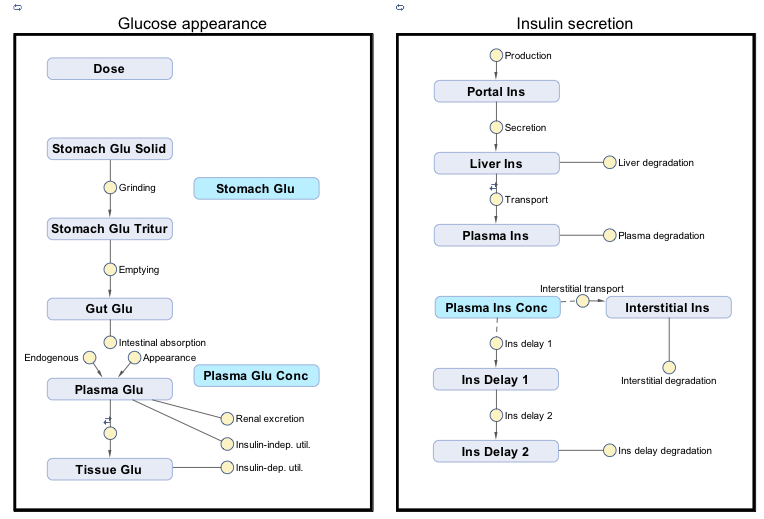

## Setup

Load the model.

sbioloadproject('insulindemo', 'm1')

Suppress an informational warning that is issued during simulations.

warnSettings = warning('off', 'SimBiology:DimAnalysisNotDone_MatlabFcn_Dimensionless');

## Simulating the Glucose-Insulin Response for a Normal Subject

Select the `Single Meal` dose object and display its properties.

mealDose = sbioselect(m1, 'Name', 'Single Meal');
get(mealDose)

ans = struct with fields:
                   Amount: 78
                 Interval: 0
                     Rate: 0
              RepeatCount: 0
                StartTime: 0
                   Active: 0
              AmountUnits: 'gram'
    DurationParameterName: ''
                EventMode: 'stop'
         LagParameterName: ''
                RateUnits: ''
               TargetName: 'Dose'
                TimeUnits: 'hour'
                     Name: 'Single Meal'
                   Parent: [1×1 SimBiology.Model]
                    Notes: ''
                      Tag: ''
                     Type: 'repeatdose'
                 UserData: []


Simulate for 7 hours.

configset = getconfigset(m1,'active');
configset.StopTime = 7;

Display the simulation time units (and `StopTime` units).

configset.TimeUnits

ans = 'hour'

Simulate a single meal for a normal subject.

normalMealSim = sbiosimulate(m1, configset, [], mealDose);

## Simulating the Glucose-Insulin Response for a Type 2 Diabetic

Select the Type 2 diabetic variant and display its properties.

diabeticVar = sbioselect(m1, 'Name', 'Type 2 diabetic')

diabeticVar =    SimBiology Variant - Type 2 diabetic (inactive)

   ContentIndex:     Type:        Name:             Property:           Value:
   1                 parameter    Plasma Volume ... Value               1.49
   2                 parameter    k1                Value               .042
   3                 parameter    k2                Value               .071
   4                 parameter    Plasma Volume ... Value               .04
   5                 parameter    m1                Value               .379
   6                 parameter    m2                Value               .673
   7                 parameter    m4                Value               .269
   8                 parameter    m5                Value               .0526
   9                 parameter    m6                Value               .8118
   10                parameter    Hepatic Extrac... Value               .6
   11                parameter    kmax              Value               .0465
   12   

Simulate a single meal for a Type 2 diabetic.

diabeticMealSim = sbiosimulate(m1, configset, diabeticVar, mealDose);

Compare the results for the most important outputs of the simulation.

- Plasma Glucose (species `Plasma Glu Conc`)

- Plasma Insulin (species `Plasma Ins Conc`)

- Endogenous Glucose Production (parameter `Glu Prod`)

- Glucose Rate of Appearance (parameter `Glu Appear Rate`)

- Glucose Utilization (parameter `Glu Util`)

- Insulin Secretion (parameter `Ins Secr`)

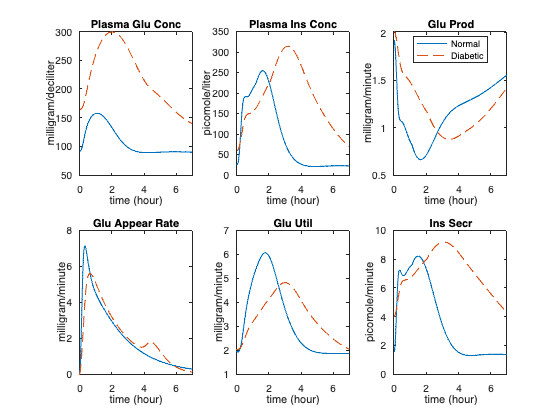

outputNames = {'Plasma Glu Conc', 'Plasma Ins Conc', 'Glu Prod', ...
    'Glu Appear Rate', 'Glu Util', 'Ins Secr'};
figure;
for i = 1:numel(outputNames)
    subplot(2, 3, i);

    [tNormal, yNormal  ]  = normalMealSim.selectbyname(outputNames{i});
    [tDiabetic, yDiabetic]  = diabeticMealSim.selectbyname(outputNames{i});
    
    plot( tNormal    , yNormal   , '-'       , ... 
          tDiabetic  , yDiabetic , '--'      );
  
    % Annotate figures 
    outputParam = sbioselect(m1, 'Name', outputNames{i});  
    title(outputNames{i});
    xlabel('time (hour)');
    if strcmp(outputParam.Type, 'parameter')
        ylabel(outputParam.ValueUnits);
    else
        ylabel(outputParam.InitialAmountUnits);
    end
    xlim([0 7]);
    
    % Add legend
    if i == 3
        legend({'Normal', 'Diabetic'}, 'Location', 'Best');
    end
    
end

Note the much higher concentrations of glucose and insulin in the plasma, as well as the prolonged duration of glucose utilization and insulin secretion.

## Simulating One Day with Three Meals for a Normal Subject

Set the simulation `StopTime` to 24 hours.

configset.StopTime = 24;

Select daily meal dose.

dayDose  = sbioselect(m1, 'Name', 'Daily Life');

Simulate three meals for a normal subject.

normalDaySim = sbiosimulate(m1, configset, [], dayDose);

## Simulating One Day with Three Meals for Impaired Subjects

Simulate the following combinations of impairments:

- Impairment 1: Low insulin sensitivity

- Impairment 2: Impairment 1 with high beta cell responsivity

- Impairment 3: Low beta cell responsivity

- Impairment 4: Impairment 3 with high insulin sensitivity

Store the impairments in a cell array.

impairVars{1} =  sbioselect(m1, 'Name', 'Low insulin sensitivity'    ) ;
impairVars{2} = [impairVars{1}, ...
                    sbioselect(m1, 'Name', 'High beta cell responsivity')];
impairVars{3} =  sbioselect(m1, 'Name', 'Low beta cell responsivity' ) ;
impairVars{4} = [impairVars{3}, ...
                    sbioselect(m1, 'Name', 'High insulin sensitivity'   )];

Simulate each impairment.

for i = 1:4
    impairSims(i) = sbiosimulate(m1, configset, impairVars{i}, dayDose);
end

Compare the plasma glucose and plasma insulin results.

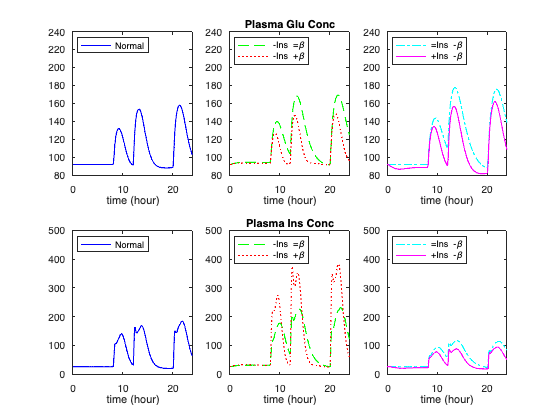

figure;
outputNames = {'Plasma Glu Conc', 'Plasma Ins Conc'};

legendLabels = {{'Normal'}, ...
    {'-Ins =\beta', '-Ins +\beta'}, ...
    {'=Ins -\beta', '+Ins -\beta'}};
yLimits = [80 240; 0 500];

for i = 1:numel(outputNames)
     
    [tNormal, yNormal] = selectbyname(normalDaySim , outputNames{i} );
    [tImpair, yImpair] = selectbyname(impairSims   , outputNames{i} );
    
    % Plot Normal
    subplot(2, 3, 3*i-2 );
    plot(tNormal, yNormal, 'b-');
    xlim([0 24]);
    ylim(yLimits(i,:));
    xlabel('time (hour)');
    legend(legendLabels{1}, 'Location', 'NorthWest');
    
    % Plot Low Insulin
    subplot(2, 3, 3*i-1 );
    plot(tImpair{1}, yImpair{1}, 'g--', tImpair{2}, yImpair{2}, 'r:');
    xlim([0 24]); 
    ylim(yLimits(i,:));
    xlabel('time (hour)');
    legend(legendLabels{2}, 'Location', 'NorthWest');
    title(outputNames{i});
    
    % Plot Low Beta
    subplot(2, 3, 3*i   );
    plot(tImpair{3}, yImpair{3}, 'c-.', tImpair{4}, yImpair{4}, 'm-');
    xlim([0 24]); 
    ylim(yLimits(i,:));
    xlabel('time (hour)');
    legend(legendLabels{3}, 'Location', 'NorthWest');
    
end

Note that either low insulin sensitivity (dashed green line,  $-Ins =\beta$) or low beta-cell sensitivity (dashed-dotted cyan line, $=Ins -\beta$) lead to increased and prolonged plasma glucose concentrations (top row of plots). Low sensitivity in one system can be partially compensated by high sensitivity in another system. For example, low insulin sensitivity and high beta-cell sensitivity (dotted red line, $-Ins +\beta$) results in relatively normal plasma glucose concentrations (top row of plots). However, in this case, the resulting plasma insulin concentration is extremely high (bottom row of plots).

## Parameter Estimation Methodology

Rather than simultaneously estimating parameters for the entire model, the authors perform parameter estimation for different subsystems of the model using a forcing function strategy. This approach requires additional experimental data for the "inputs" of the submodel. During fitting, the input data determine the dynamics of the inputs species. (In the full model, the dynamics of the inputs are determined from the differential equations.) In SimBiology terms, you can implement a forcing function as a repeated assignment rule that controls the value of a species or parameter that serves as an input for a subsystem of the model. In the following sections, we use the parameter fitting capabilities of SimBiology to refine the authors' reported parameter values.

## Fitting the Gastrointestinal Model of Glucose Appearance Using `nlinfit`

The gastrointestinal model represents how glucose in a meal is transported through the stomach, gut, and intestine, and then absorbed into the plasma. The input to this subsystem is the amount of glucose in a meal, and the output is the rate of appearance of glucose in the plasma. However, we also estimate the meal size since the value reported by the authors is inconsistent with the parameters and simulation results. Because this input only occurs at the start of the simulation, no forcing function is required.

The function `sbiofit` supports the estimation of parameters in SimBiology models using several different algorithms from MATLAB™, Statistics and Machine Learning Toolbox, Optimization Toolbox, and Global Optimization Toolbox. First, estimate the parameters using Statistics and Machine Learning Toolbox function `nlinfit`.

% Load the experimental data
fitData = groupedData(readtable('GlucoseData.csv', 'Delimiter', ','));

% Set the units on the data
fitData.Properties.VariableUnits = {...
    'hour', ...                % Time units
    'milligram/minute', ...    % GluRate units
    'milligram/deciliter', ... % PlasmaGluConc units
    'milligram/minute', ...    % GluUtil units
    };

% Identify which model components corresponds to observed data variables.
gastroFitObs = '[Glu Appear Rate] = GluRate';

% Estimate the value of the following parameters:
gastroFitEst = estimatedInfo({'kmax', 'kmin', 'kabs', 'Dose'});

% Ensure the parameter estimates are always positive during estimation by
% using a log transform on all parameters.
[gastroFitEst.Transform] = deal('log');

% Set the initial estimate for Dose to the reported meal dose amount. The
% remaining initial estimates will be taken from the parameter values in
% the model.
gastroFitEst(4).InitialValue = mealDose.Amount;

% Generate simulation data with the initial parameter estimates
configset.StopTime = 7;
gastroInitSim = sbiosimulate(m1, mealDose);
 
% Fit the data using |nlinfit|, displaying output at each iteration
fitOptions = statset('Display', 'iter');
[gastroFitResults, gastroFitSims] = sbiofit(m1, fitData, ...
    gastroFitObs, gastroFitEst, [], 'nlinfit', fitOptions);

 
                                     Norm of         Norm of
   Iteration             SSE        Gradient           Step 
  -----------------------------------------------------------
           0          43.798
           1         2.23537         22.9971        0.596828
           2         1.65217         1.33015        0.107431
           3          1.6491       0.0778863       0.0239157
           4         1.64909     0.000590451      0.00225498
           5         1.64908       0.0281221     4.92368e-05
           6         1.64908       0.0973156     1.16488e-16
Iterations terminated: relative norm of the current step is less than OPTIONS.TolX


## Fitting the Data Using `fminunc`

Now, estimate the parameters using the Optimization Toolbox function `fminunc`.

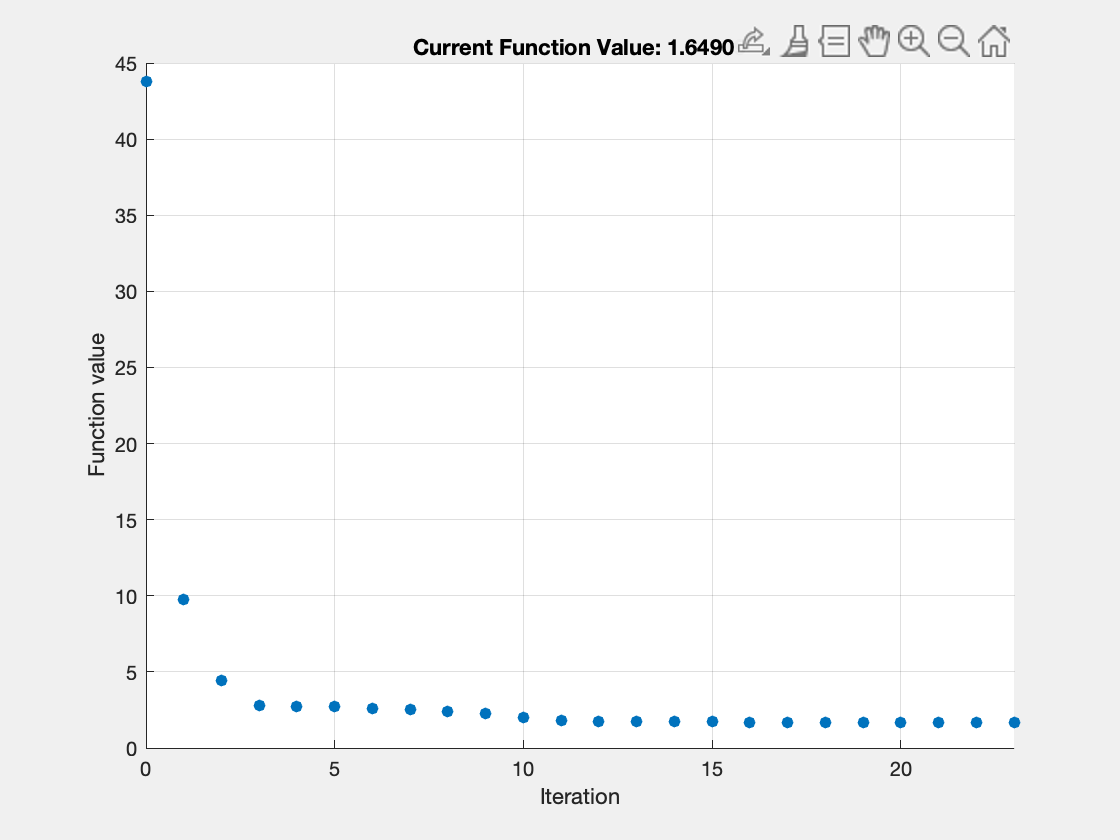

% Fit the data, plotting the objective function at each iteration
fitOptions2 = optimoptions('fminunc', 'PlotFcns', @optimplotfval);
[gastroFitResults(2), gastroFitSims(2)] = sbiofit(m1, fitData, ...
    gastroFitObs, gastroFitEst, [], 'fminunc', fitOptions2);

Compare the simulation before and after fitting.

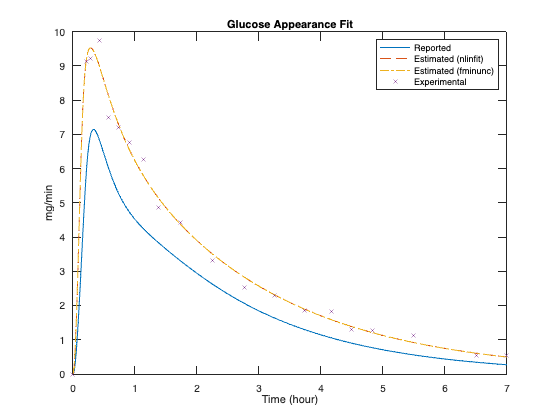

gastroSims = selectbyname([gastroInitSim gastroFitSims], 'Glu Appear Rate');

figure;
plot(gastroSims(1).Time , gastroSims(1).Data , '-'  , ...
     gastroSims(2).Time , gastroSims(2).Data , '--' , ...
     gastroSims(3).Time , gastroSims(3).Data , '-.' , ...
     fitData.Time       , fitData.GluRate, 'x'  );
 
xlabel('Time (hour)');
ylabel('mg/min');
legend('Reported', 'Estimated (nlinfit)', ...
    'Estimated (fminunc)', 'Experimental');
title('Glucose Appearance Fit');

Plot the change in parameter values, relative to reported values.

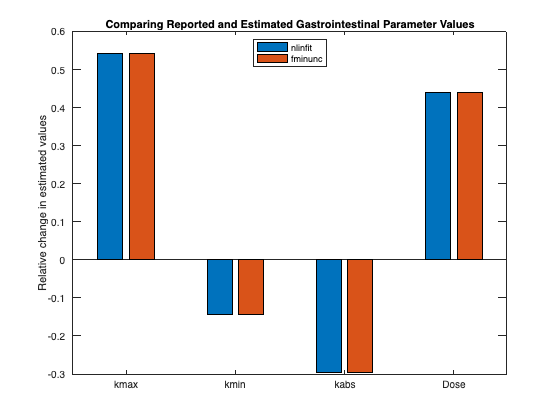

figure;
fitResults = [gastroFitResults(1).ParameterEstimates.Estimate ...
    gastroFitResults(2).ParameterEstimates.Estimate];
% The initial values for kmax, kmin, and kabs come from the model.
gastroFitInitValues = [
    get(sbioselect(m1, 'Name', 'kmax'), 'Value')
    get(sbioselect(m1, 'Name', 'kmin'), 'Value')
    get(sbioselect(m1, 'Name', 'kabs'), 'Value')
    gastroFitEst(4).InitialValue
    ];
relFitChange = fitResults ./ [gastroFitInitValues gastroFitInitValues] - 1;
bar(relFitChange);
ax = gca;
ax.XTickLabel = {gastroFitEst.Name};
ylabel('Relative change in estimated values');
title('Comparing Reported and Estimated Gastrointestinal Parameter Values');
legend({'nlinfit', 'fminunc'}, 'Location', 'North')

Note that the model fits the experimental data significantly better if the meal size (`Dose`) is significantly larger than reported, the parameter `kmax` is significantly larger than reported, and `kabs` is smaller than reported.

## Fitting the Muscle and Adipose Tissue Model of Glucose Utilization

The muscle and adipose tissue model represents how glucose is utilized in the body. The "inputs" to this subsystem are the concentration of insulin in the plasma (`Plasma Ins Conc`), the endogenous glucose production (`Glu Prod`), and the rate of appearance of glucose (`Glu Appear Rate`). The "outputs" are the concentration of glucose in the plasma (`Plasma Glu Conc`) and the rate of glucose utilization (`Glu Util`).

Because the inputs are a function of time, they need to be implemented as forcing functions. Specifically, the values of `Plasma Ins Conc`, `Glu Prod`, and `Glu Appear Rate` are controlled by repeated assignments that call functions to do linear interpolation of the reported experimental values. When using these functions to control a species or parameter, you must make inactive any other rule that is used to set its value. To facilitate the selection of these rules, the rule Name properties contain meaningful names.

% Create forcing functions for the "inputs":
% Plasma Insulin
PlasmaInsRule       = sbioselect(m1, 'Name', 'Plasma Ins Conc definition');
PlasmaInsForcingFcn = sbioselect(m1, 'Name', 'Plasma Ins Conc forcing function')

PlasmaInsForcingFcn =    SimBiology Rule Array

   Index:    RuleType:             Rule:                                                                  
   1         repeatedAssignment    [Plasma Ins Conc] = [picomole per liter]*PlasmaInsulin(time/[one hour])


PlasmaInsRule.Active       = false;
PlasmaInsForcingFcn.Active = true;

% Endogenous Glucose Production (Glu Prod)
GluProdRule       = sbioselect(m1, 'Name', 'Glu Prod definition');
GluProdForcingFcn = sbioselect(m1, 'Name', 'Glu Prod forcing function')

GluProdForcingFcn =    SimBiology Rule Array

   Index:    RuleType:             Rule:                                                                           
   1         repeatedAssignment    [Glu Prod] = [milligram per minute]*EndogenousGlucoseProduction(time/[one hour])


GluProdRule.Active       = false;
GluProdForcingFcn.Active = true;

% Glucose Rate of Appearance (Glu Appear Rate)
GluRateRule       = sbioselect(m1, 'Name', 'Glu Appear Rate definition');
GluRateForcingFcn = sbioselect(m1, 'Name', 'Glu Appear Rate forcing function')

GluRateForcingFcn =    SimBiology Rule Array

   Index:    RuleType:             Rule:                                                                            
   1         repeatedAssignment    [Glu Appear Rate] = [milligram per minute]*GlucoseAppearanceRate(time/[one hour])


GluRateRule.Active       = false;
GluRateForcingFcn.Active = true;

% Simulate with the initial parameter values
muscleInitSim = sbiosimulate(m1);

% Identify which model components corresponds to observed data variables.
muscleFitObs = {'[Plasma Glu Conc] = PlasmaGluConc', ...
    '[Glu Util] = GluUtil'};

% Estimate the value of the following parameters:
muscleFitEst = estimatedInfo({'[Plasma Volume (Glu)]', 'k1', 'k2', ...
    'Vm0', 'Vmx', 'Km', 'p2U'});

% Ensure the parameter estimates are always positive during estimation by
% using a log transform on all parameters.
[muscleFitEst.Transform] = deal('log');

% Fit the data, displaying output at each iteration 
[muscleFitResults, muscleFitSim] = sbiofit(m1, fitData, ...
    muscleFitObs, muscleFitEst, [], 'nlinfit', fitOptions);

 
                                     Norm of         Norm of
   Iteration             SSE        Gradient           Step 
  -----------------------------------------------------------
           0         2181.52
           1         680.897         23725.2        0.614745
           2         491.291         4668.05        0.639149
           3         426.762         6049.38        0.546668
           4         386.533         12069.5         0.17472
           5         287.733         6665.72        0.113794
           6         246.614          3976.7        0.206679
           7         242.785         1695.29        0.162998
           8          234.51         3841.21        0.191015
           9         230.144         4046.85        0.159911
          10         224.303         1250.28        0.060387
          11         218.085         629.066       0.0412896
          12         217.148          1912.5       0.0527436
          13         216.686         1536.59       0.

Plot the change in parameter values, relative to reported values.

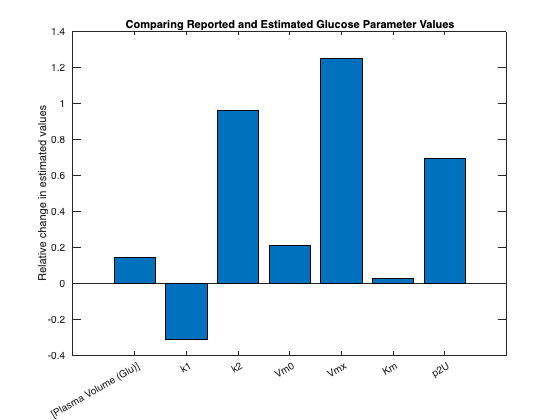

figure;
muscleFitInitValues = [
    get(sbioselect(m1, 'Name', 'Plasma Volume (Glu)'), 'Value')
    get(sbioselect(m1, 'Name', 'k1'), 'Value')
    get(sbioselect(m1, 'Name', 'k2'), 'Value')
    get(sbioselect(m1, 'Name', 'Vm0'), 'Value')
    get(sbioselect(m1, 'Name', 'Vmx'), 'Value')
    get(sbioselect(m1, 'Name', 'Km'), 'Value')
    get(sbioselect(m1, 'Name', 'p2U'), 'Value')
    ];

bar(muscleFitResults.ParameterEstimates.Estimate ./ muscleFitInitValues - 1);
ax = gca;
ax.XTickLabel = {muscleFitEst.Name};
ylabel('Relative change in estimated values');
title('Comparing Reported and Estimated Glucose Parameter Values');

Clean up the changes to the model.

PlasmaInsRule.Active = true;
GluProdRule.Active   = true;
GluRateRule.Active   = true;

PlasmaInsForcingFcn.Active = false;
GluProdForcingFcn.Active   = false;
GluRateForcingFcn.Active   = false;

Compare the simulation before and after fitting

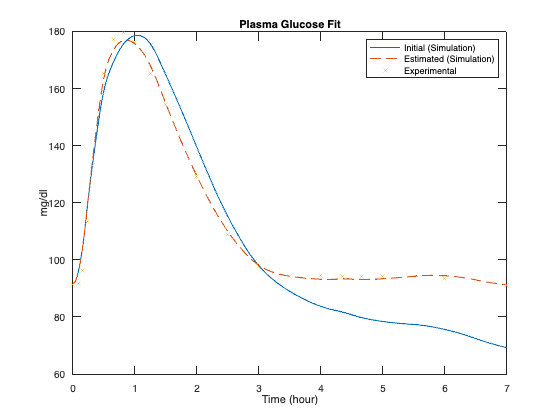

muscleSims = selectbyname([muscleInitSim muscleFitSim], ...
    {'Plasma Glu Conc', 'Glu Util'});
figure;
plot(muscleSims(1).Time, muscleSims(1).Data(:,1), '-', ...
    muscleSims(2).Time, muscleSims(2).Data(:,1), '--', ...
    fitData.Time, fitData.PlasmaGluConc, 'x');
xlabel('Time (hour)');
ylabel('mg/dl');
legend('Initial (Simulation)', 'Estimated (Simulation)', 'Experimental');
title('Plasma Glucose Fit');

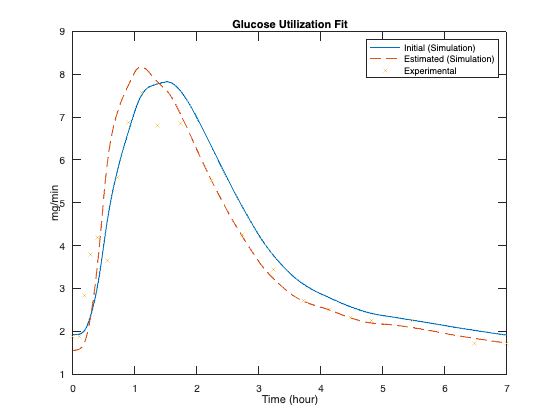

figure;
plot(muscleSims(1).Time, muscleSims(1).Data(:,2), '-', ...
    muscleSims(2).Time, muscleSims(2).Data(:,2), '--', ...
    fitData.Time, fitData.GluUtil, 'x');
xlabel('Time (hour)');
ylabel('mg/min');
legend('Initial (Simulation)', 'Estimated (Simulation)', 'Experimental');
title('Glucose Utilization Fit');

Note that significantly increasing some parameters, such as `Vmx`, allows a much better fit of late-time plasma glucose concentrations.

## Cleanup

Restore warning settings.

warning(warnSettings);

## Conclusions

SimBiology contains several features that facilitate the implementation and simulation of a complex model of the glucose-insulin system. Reactions, events, and rules provide a natural way to describe the dynamics of the system. Unit conversion allows species and parameters to be specified in convenient units and ensures the dimensional consistency of the model. Dose objects are a simple way to describe recurring inputs to a model, such as the daily meal schedule in this example. SimBiology also provides built-in support for analysis tasks like simulation and parameter estimation.

*Copyright 2011-2014 The MathWorks, Inc.*